# Using Ground Truth for Object Detection : Part 1

Copyright 2018 The MathWorks, Inc.

## Play the sample video

vidReader = VideoReader('BuoyRun2GT.mp4');
vidPlayer = vision.DeployableVideoPlayer;
while(hasFrame(vidReader))    
    I = readFrame(vidReader);    
    step(vidPlayer,I);
    pause(0.05);
end

## Open the Ground Truth Labeler App

Open an instance of the Ground Truth Labeller

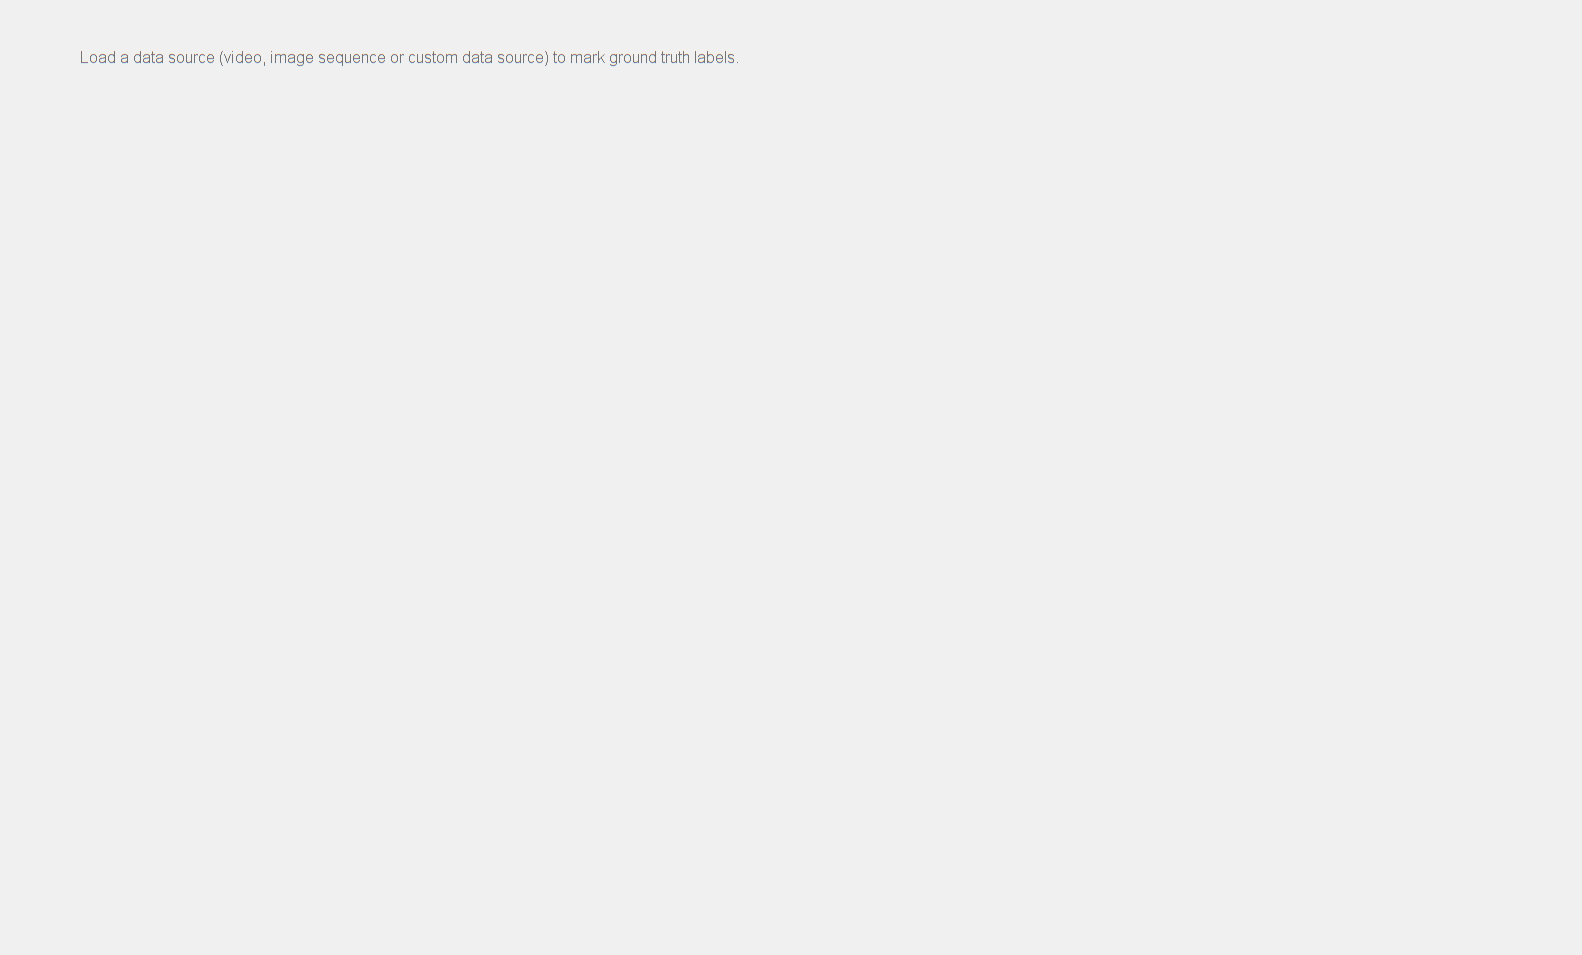

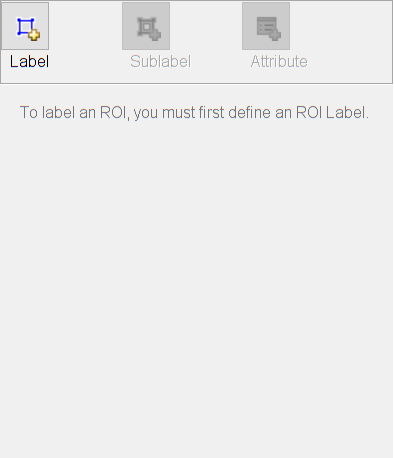

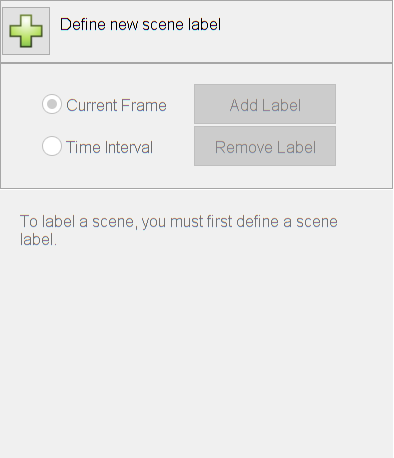

groundTruthLabeler;

## Open a Pre-Labeled Ground Truth Session

groundTruthLabeler('groundTruthLabelingSessionPart1.mat');

## Save labels to a MAT file

save('gTruthTraining.mat','gTruth')